## Curva de Linealidad

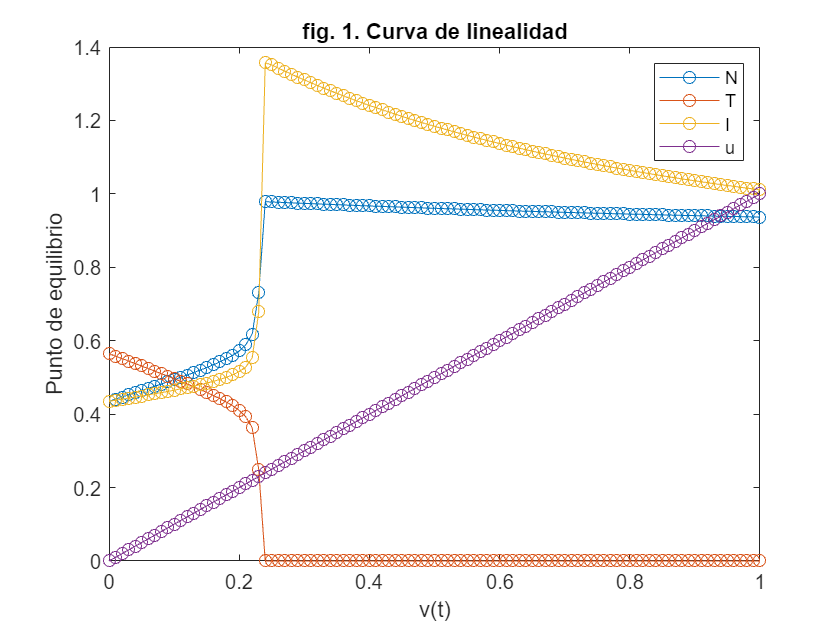

t=0:0.1:200;
vs=[t' ones(size(t,2),1)];
step=0:0.01:1;
Nf=zeros(length(step),1);
If=zeros(length(step),1);
Tf=zeros(length(step),1);
uf=zeros(length(step),1);
for i=1:length(step)
    v=vs;
    v(:,2)=step(i)*vs(:,2);
    sim("ModeloPractica")
    Nf(i)=N(end);
    Tf(i)=T(end);
    If(i)=I(end);
    uf(i)=u(end);
end
plot(step,[Nf Tf If uf],'-o')
xlabel("v(t)")
ylabel("Punto de equilibrio")
title("fig. 1. Curva de linealidad")
legend(["N", "T", "I", "u"])

## Periodo de Muestreo

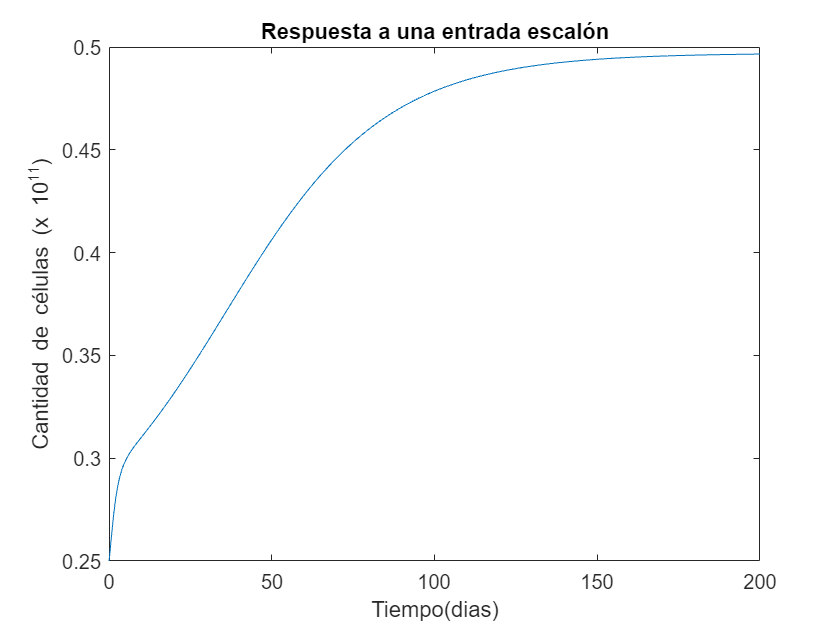

ci=[1 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
t=0:0.1:200;
v=[t' 0.1*ones(length(t),1)];
sim("ModeloPractica")
plot(t,T)
xlabel("Tiempo(dias)")
ylabel("Cantidad de células (x 10^{11})")
title("Respuesta a una entrada escalón")

T=round(T,3);
peq=T(end);
eq=find(T==peq,1,'first');
dif=peq-T0;
t1=find(T-T0>=0.1*dif,1,'first');
t1=t(t1)

t1 = 1.6000

t2=find(T-T0>=0.9*dif,1,'first');
t2=t(t2)

t2 = 92

tr=t2-t1

tr = 90.4000

Ts=round(tr/10,1)

Ts = 9